[Homogenous Propagation Medium](https://www.k-wave.org/documentation/example_ivp_homogeneous_medium.php)

Demostracion de simulacion y deteccion de campos de presiones generados por una presion inicial ditribuida en un medio de propagacion homogeneo.

Pasos: space, medium, source, sensor

makeDisc(): crea una forma geometrica (punto de la malla) donde existira una presion inicial que genere la onda.

source.p0(): representa **todo el mapa inicial de presión, **define la fuente física para la simulación.

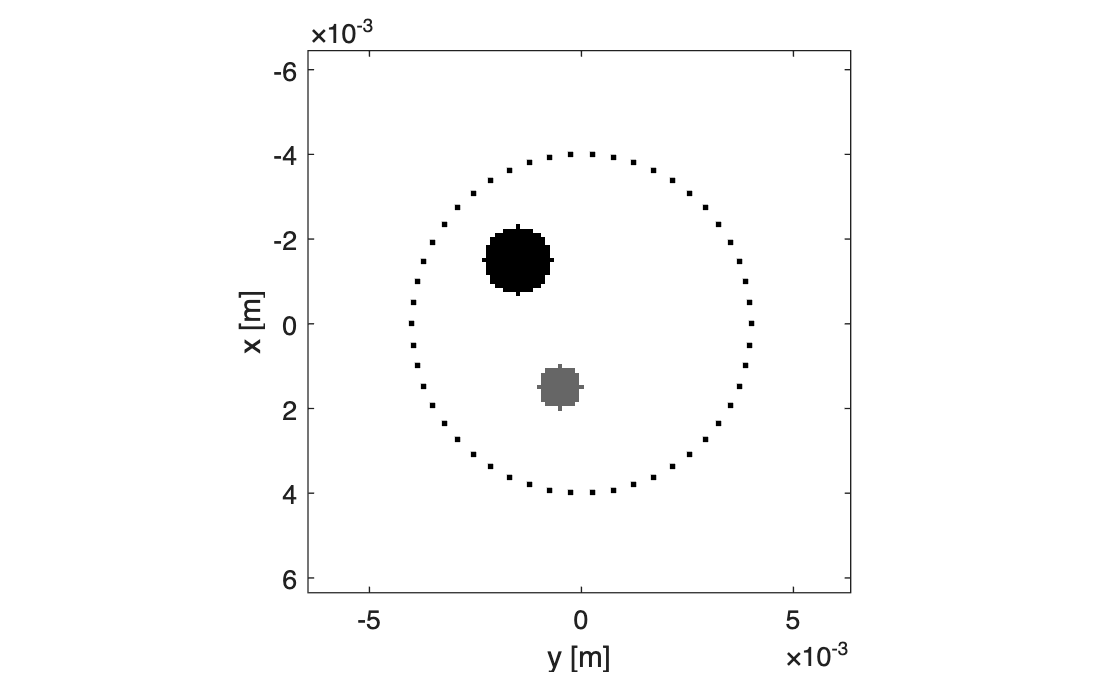

clear all
%Creamos espacio para trabajar en mm se trabajara 1e-3
Nx = 128;           % number of grid points in the x (row) direction
Ny = 128;           % number of grid points in the y (column) direction
dx = 0.1e-3;        % grid point spacing in the x direction [m]
dy = 0.1e-3;        % grid point spacing in the y direction [m]

kgrid = kWaveGrid(Nx, dx, Ny, dy);

%Definimos el medio por el cual propagaremos la onda 
medium.sound_speed = 1500;  % [m/s]
medium.alpha_coeff = 0.75;  % [dB/(MHz^y cm)]
medium.alpha_power = 1.5;

%Crea dos fuente con sus propios parametros
disc_magnitude = 5; % [Pa]
disc_x_pos = 50;    % [grid points]
disc_y_pos = 50;    % [grid points]
disc_radius = 8;    % [grid points]

%Genero presion 1
disc_1 = disc_magnitude * makeDisc(Nx, Ny, disc_x_pos, disc_y_pos, disc_radius);

disc_magnitude = 3; % [Pa]
disc_x_pos = 80;    % [grid points]
disc_y_pos = 60;    % [grid points]
disc_radius = 5;    % [grid points]

%Genero presion 1
disc_2 = disc_magnitude * makeDisc(Nx, Ny, disc_x_pos, disc_y_pos, disc_radius);

%Ubica las presiones iniciales 1 y 2 en la misma malla en los lugares
%predefinidos, para generar las fuentes.
source.p0 = disc_1 + disc_2;

%Ejemplo de la distribucion que se hace manualmente en la Malla Nx × Ny

%(1,1)
%┌───────────────────────────┐
%│                           │
%│      ● fuente 1           │
%│                           │
%│                 ● fuente 2│
%│                           │
%└───────────────────────────┘
%                        (Nx,Ny)

% define a centered circular sensor

%Sirve para colocar los puntos que grabaran los datos.
sensor_radius = 4e-3;   % [m]
num_sensor_points = 50;
sensor.mask = makeCartCircle(sensor_radius, num_sensor_points);

%ploteo para ver distribucion a partir de source y sensor.mask
figure;
imagesc(kgrid.y_vec, kgrid.x_vec,max(source.p0(:))-source.p0); %invierto colores para fondo blanco
colormap(gray);
hold on;
plot(sensor.mask(2,:), sensor.mask(1,:), 'k.');
axis image;
xlabel('y [m]');
ylabel('x [m]');

En la simulacion aparecera todo completo

% run the simulation
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor,'Smooth', false);

Running k-Wave simulation...
  start time: 26-Aug-2026 11:03:08
  reference sound speed: 1500m/s
  dt: 20ns, t_end: 12.06us, time steps: 604
  input grid size: 128 by 128 grid points (12.8 by 12.8mm)
  maximum supported frequency: 7.5MHz
  calculating Delaunay triangulation...
  precomputation completed in 0.37189s
  starting time loop...
  estimated simulation time 7.9839s...
  simulation completed in 4.121s
  total computation time 4.5411s


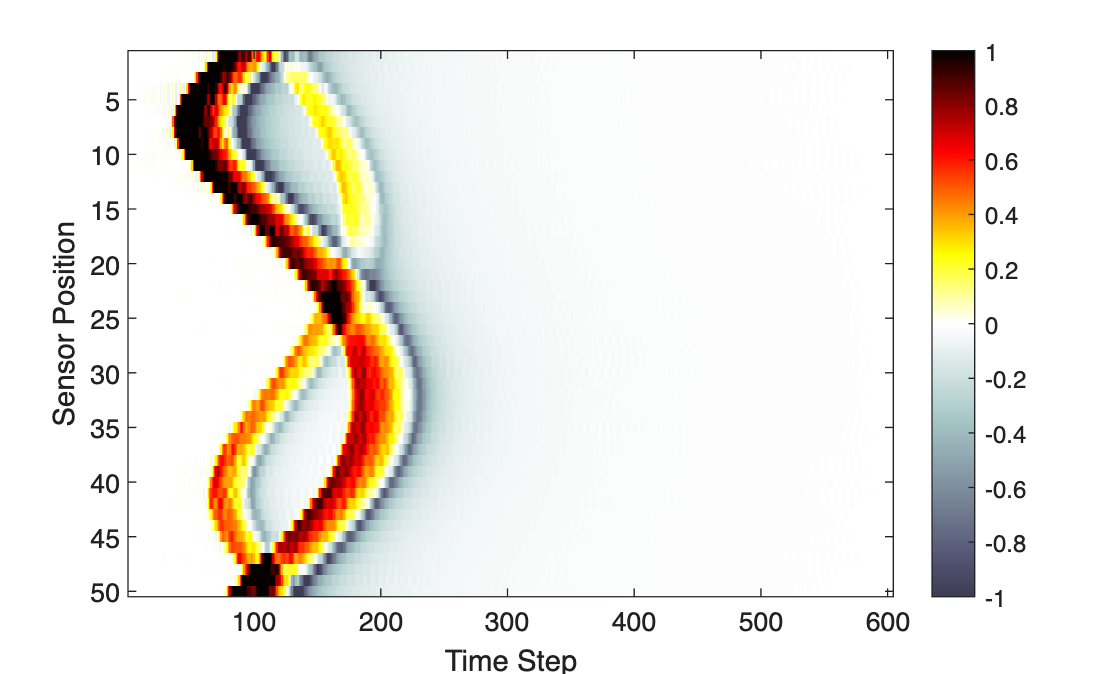

% para plotear la simulacion se puede usar imagesc tambien
figure;
imagesc(sensor_data, [-1, 1]);
colormap(getColorMap);
ylabel('Sensor Position');
xlabel('Time Step');
colorbar;

Se puede ver que la onda **no llega a todos los sensores al mismo tiempo, pues **los sensores más cercanos a cada fuente registran antes la onda, mientras que los ubicados más lejos la detectan después. Esto es coherente, pues la curvatura de las bandas representa precisamente esa variación de distancia fuente–sensor. Además, las dos distribuciones de presión inicial generan frentes que se superponen, produciendo zonas donde las señales se acercan o cruzan alrededor de los sensores centrales.

[Using A Binary Sensor Mask](https://www.k-wave.org/documentation/example_ivp_binary_sensor_mask.php)

Un **binary sensor mask** es una matriz del mismo tamaño que la malla donde a diferencia de** cartesian mask (**makeCircle), que te da coordenadas cartesianas (es decir yo coloco donde poner los sensores en la malla), una máscara binaria ya viene “dibujada” sobre la propia malla `Nx × Ny.`

- `En binary mask: yo defino geometria no cuantos sensores:`

`        makeCircle(Nx, Ny, cx, cy, radius, arc_angle)`

- `En cartesian mask: yo defino numero de sensores y el radio y el centro de la circunferencia.`

`        makeCartCircle(radius, num_points, center)`

`Son practicamente iguales de inicializar, con la diferencia que Nx Ny: esta relacionado con el lienzo donde dibujara la circunferencia con radio (radius) y su centro (cx, cy). `

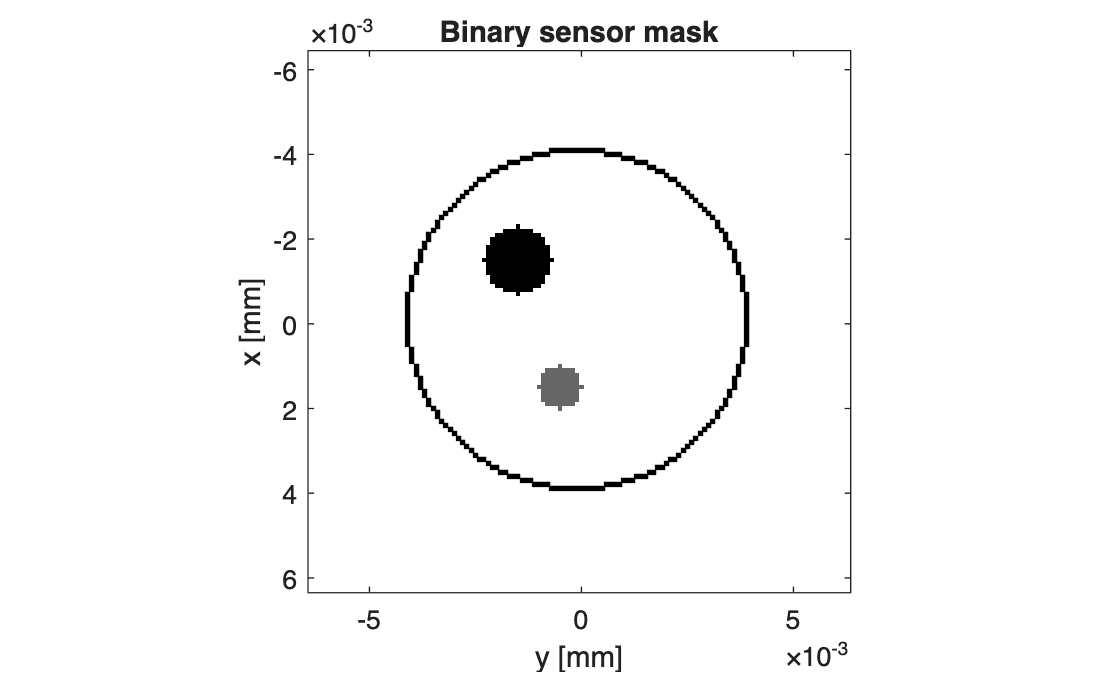

%Binary mask
%●---●---●---●
%        ↑
%   sensor justo en un nodo

% Sensor binario

%marca con 1 todos los nodos de la malla que aproximan un círculo de radio 40 puntos.
sensor.mask = makeCircle(Nx, Ny, Nx/2, Ny/2, 40); 

%ploteo para ver distribucion a partir de source y sensor.mask, se puede
%utilizar *1e3 para cambiar de
figure;
imagesc(kgrid.y_vec, kgrid.x_vec,max(source.p0(:))-source.p0); %invierto colores para fondo blanco
colormap(gray);
hold on;
[row, col] = find(sensor.mask); %no son coordenadas cartesianas, sino 1 0
plot(kgrid.y_vec(col),kgrid.x_vec(row),'k.');
axis image;
xlabel('y [mm]');
ylabel('x [mm]');
title('Binary sensor mask');

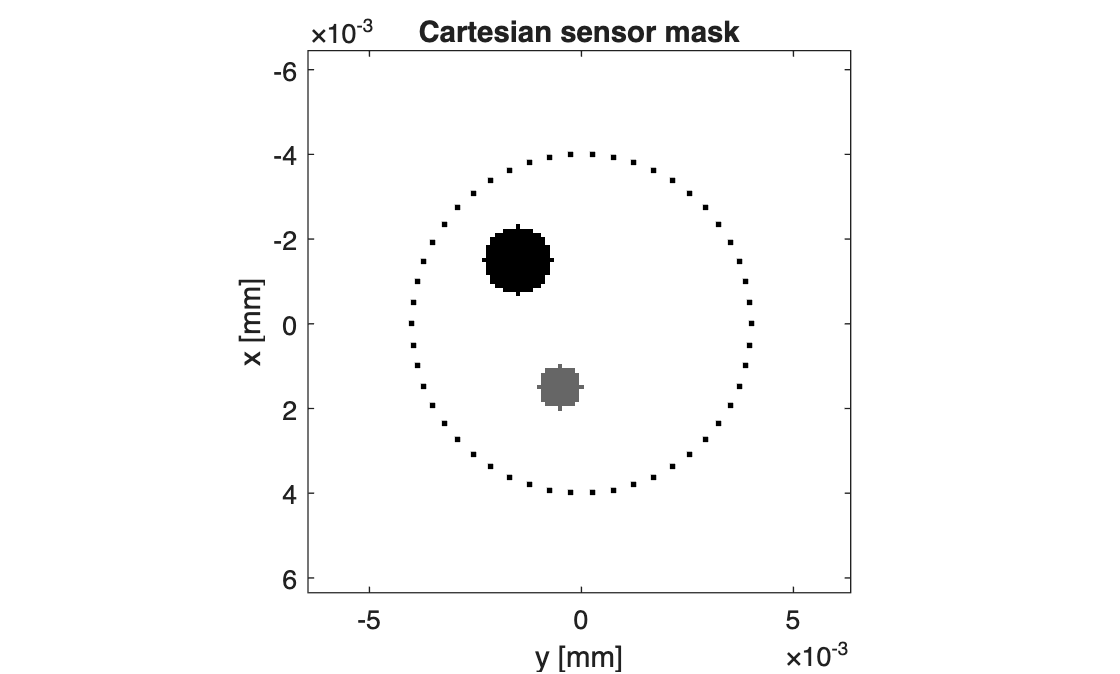


%Cartesian mask
%●---●---●---●
%      ↑
% Sensor cartesiano: coloca 50 sensores en posiciones cartesianas sobre un círculo de 4 mm.
sensor.mask = makeCartCircle(4e-3, 50);

figure;
imagesc(kgrid.y_vec, kgrid.x_vec, max(source.p0(:))-source.p0);
colormap(gray);
hold on;
plot(sensor.mask(2,:), sensor.mask(1,:), 'k.');
axis image; %mantenga la misma escala en X y Y
xlabel('y [mm]');
ylabel('x [mm]');
title('Cartesian sensor mask');

**Resumen:**

Ahora por ejemplo

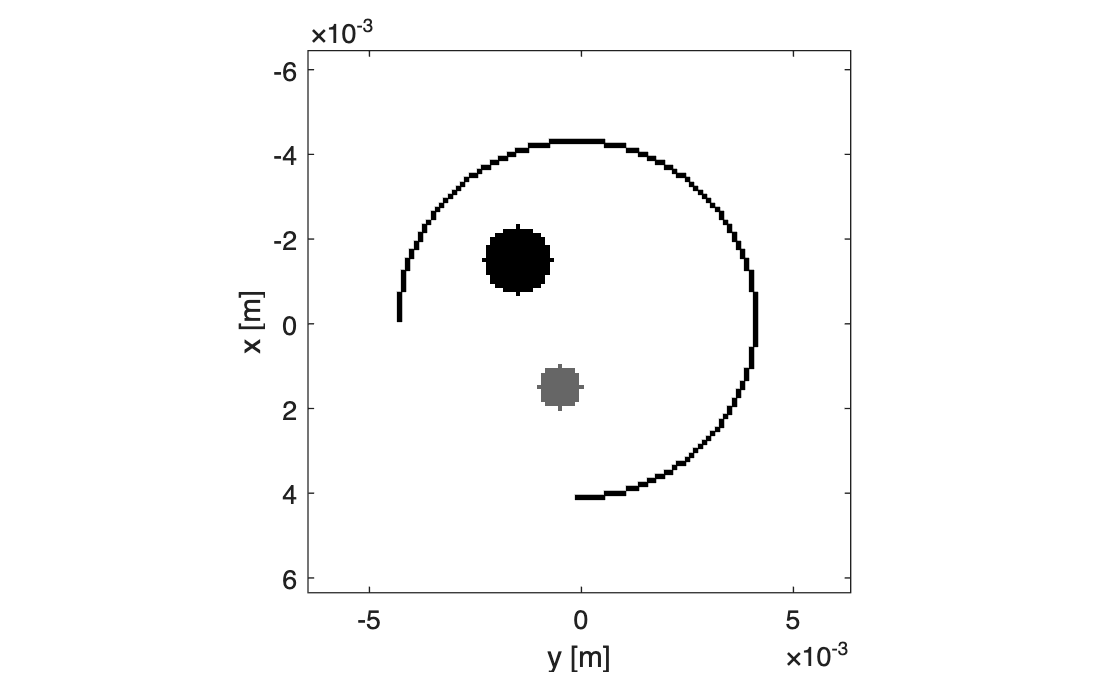

% define a binary sensor mask
sensor_x_pos = Nx/2;        % [grid points]
sensor_y_pos = Ny/2;        % [grid points]
sensor_radius = Nx/2 - 22;  % [grid points]
sensor_arc_angle = 3*pi/2;  % [radians]
sensor.mask = makeCircle(Nx, Ny, sensor_x_pos, sensor_y_pos, sensor_radius, sensor_arc_angle);

%ploteo para ver distribucion a partir de source y sensor.mask
figure;
imagesc(kgrid.y_vec, kgrid.x_vec,max(source.p0(:))-source.p0); %invierto colores para fondo blanco
colormap(gray);
hold on;
[row, col] = find(sensor.mask); %no son coordenadas cartesianas, sino 1 0
plot(kgrid.y_vec(col),kgrid.x_vec(row),'k.');
axis image;
xlabel('y [m]');
ylabel('x [m]');

%corro simulacion
sensor_data_binary_mask=kspaceFirstOrder2D(kgrid,medium,source,sensor,"Smooth", false);

Running k-Wave simulation...
  start time: 26-Aug-2026 11:15:20
  reference sound speed: 1500m/s
  dt: 20ns, t_end: 12.06us, time steps: 604
  input grid size: 128 by 128 grid points (12.8 by 12.8mm)
  maximum supported frequency: 7.5MHz
  precomputation completed in 0.15541s
  starting time loop...
  estimated simulation time 4.1042s...
  simulation completed in 3.5416s
  total computation time 3.7128s


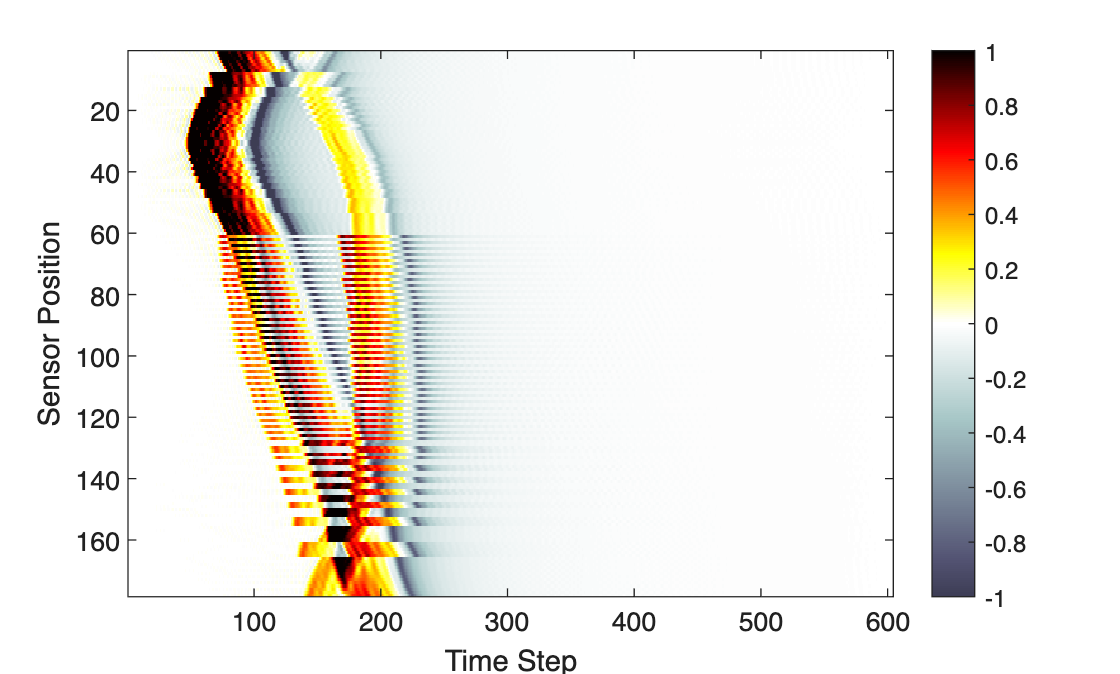

% Para plotear la simulacion se puede usar imagesc tambien
figure;
imagesc(sensor_data_binary_mask, [-1, 1]);
colormap(getColorMap);
ylabel('Sensor Position');
xlabel('Time Step');
colorbar;

Al estar incompleto esto hace que algunos frentes que en el arreglo completo se ven claramente ahora aparezcan truncados o incompletos. No significa que la onda haya desaparecido en esa zona; simplemente **no existe un sensor allí para registrarla**. Ademas encontramos que hay muchos mas sensores porque a diferencia de cartesion Mask, en binary interpola y forma al rededor del circulo no definiendo cuantos sensores

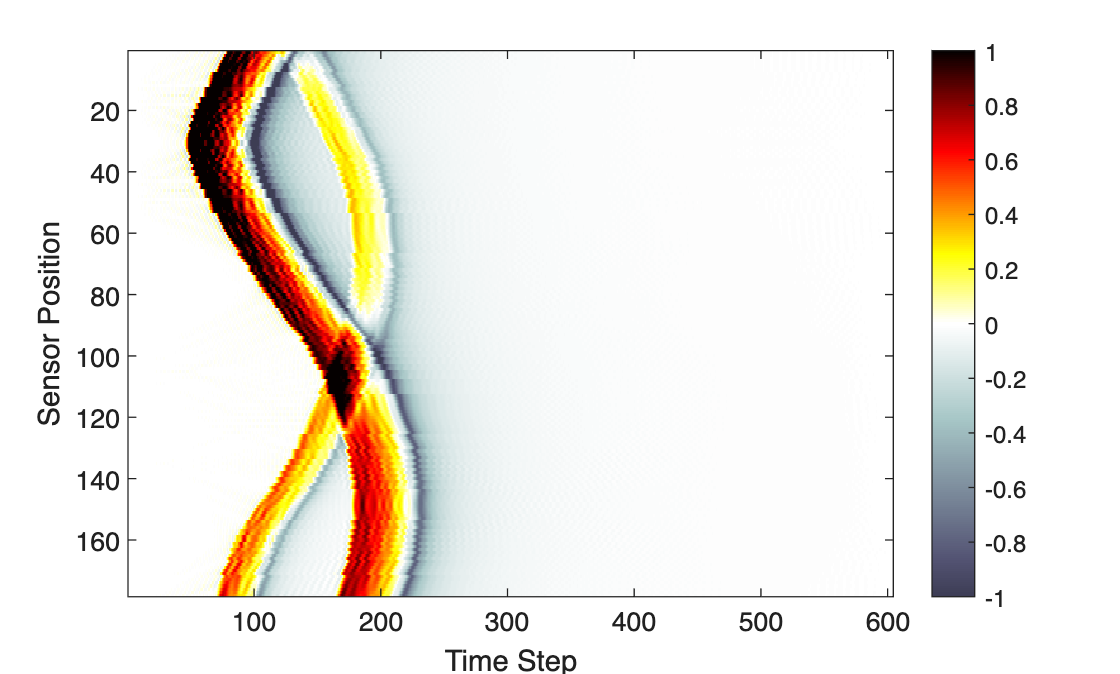

%toma los datos de una binary sensor mask y los reordena según el ángulo que cada sensor forma respecto al origen de la malla.
sensor_data_reordered = reorderSensorData(kgrid, sensor, sensor_data_binary_mask);

% Para plotear la simulacion se puede usar imagesc tambien
figure;
imagesc(sensor_data_reordered, [-1, 1]);
colormap(getColorMap);
ylabel('Sensor Position');
xlabel('Time Step');
colorbar;

[Defining A Sensor Mask By Opposing Corners](https://www.k-wave.org/documentation/example_ivp_opposing_corners_sensor_mask.php)

Se explicara como definir una mascara de sensores de forma manual con coordenadas puntuales en partes opuestas:

In addition to the Cartesian and binary sensor masks used in the previous two examples, it is also possible to define a sensor mask using the grid coordinates of two opposing corners of a line (1D), rectangle (2D), or cuboid (3D).

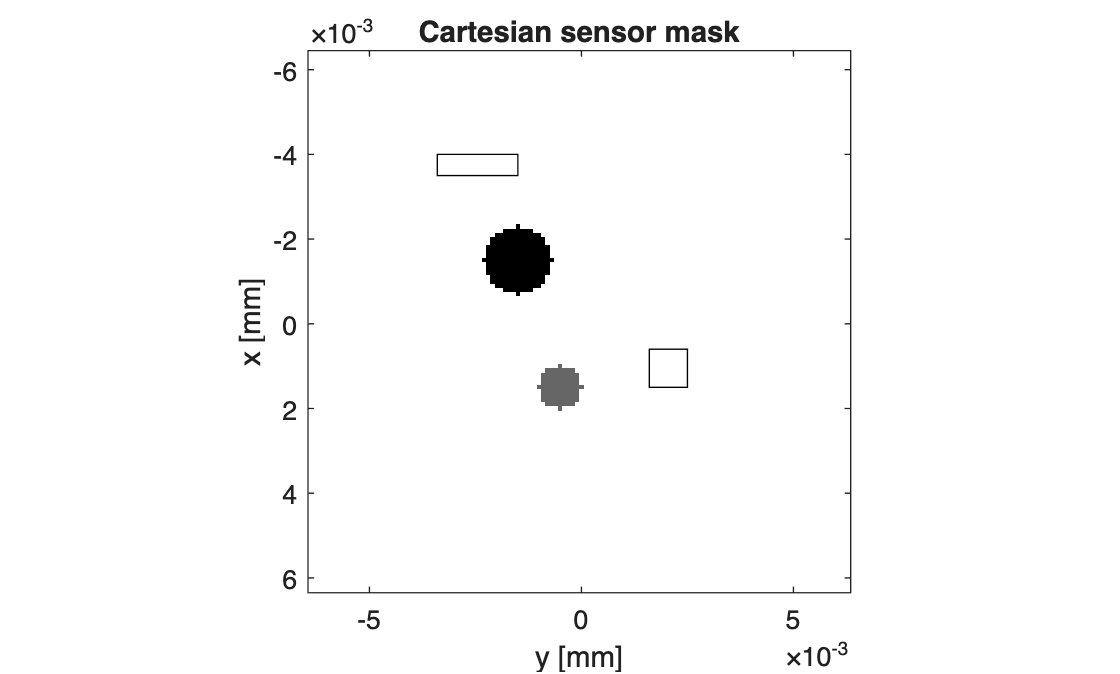

% define the first rectangular sensor region by specifying the location of
% opposing corners
rect1_x_start = 25;
rect1_y_start = 31;
rect1_x_end = 30;
rect1_y_end = 50;

% define the second rectangular sensor region by specifying the location of
% opposing corners
rect2_x_start = 71;
rect2_y_start = 81;
rect2_x_end = 80;
rect2_y_end = 90;

% assign the list of opposing corners to the sensor mask
sensor.mask = [rect1_x_start, rect1_y_start, rect1_x_end, rect1_y_end;...
               rect2_x_start, rect2_y_start, rect2_x_end, rect2_y_end].';

% Plot de como esta arreglado los sensores alrededor:
figure;
imagesc(kgrid.y_vec, kgrid.x_vec, max(source.p0(:))-source.p0);
colormap(gray);
hold on;

rectangle('Position',[kgrid.y_vec(rect1_y_start),kgrid.x_vec(rect1_x_start),kgrid.y_vec(rect1_y_end)-kgrid.y_vec(rect1_y_start),kgrid.x_vec(rect1_x_end)-kgrid.x_vec(rect1_x_start)],'EdgeColor','k');
rectangle('Position',[kgrid.y_vec(rect2_y_start),kgrid.x_vec(rect2_x_start),kgrid.y_vec(rect2_y_end)-kgrid.y_vec(rect2_y_start),kgrid.x_vec(rect2_x_end)-kgrid.x_vec(rect2_x_start)],'EdgeColor','k');

axis image;
 
xlabel('y [mm]');
ylabel('x [mm]');
title('Cartesian sensor mask');

% Simulacion del caso
simulation_data_opposite=kspaceFirstOrder2D(kgrid, medium, source, sensor, "Smooth", false);

Running k-Wave simulation...
  start time: 26-Aug-2026 11:41:30
  reference sound speed: 1500m/s
  dt: 20ns, t_end: 12.06us, time steps: 604
  input grid size: 128 by 128 grid points (12.8 by 12.8mm)
  maximum supported frequency: 7.5MHz
  precomputation completed in 0.076384s
  starting time loop...
  estimated simulation time 2.5712s...
  simulation completed in 4.285s
  reordering cuboid corners data...
  total computation time 4.3787s


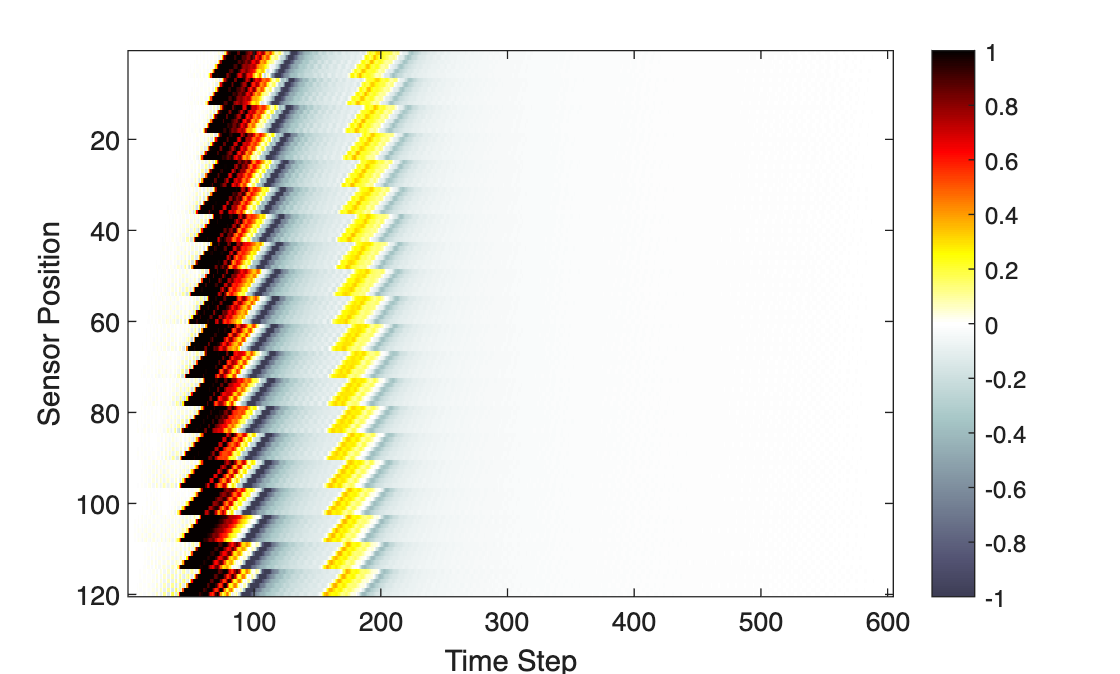

% Plotear simulacion para rectangulos de forma individual
figure;
p1=simulation_data_opposite(1).p;
p1=reshape(p1,[],size(p1,3));

imagesc(p1, [-1, 1]);
colormap(getColorMap);
ylabel('Sensor Position');
xlabel('Time Step');
colorbar;

[](https://www.k-wave.org/documentation/example_ivp_loading_external_image.php)